%% Undamped Free Vibration Analysis of SDOF Mass-Spring System
clc; clear; close all;

% Given parameters
m = 5;          % Mass in kg
k = 2000;       % Spring stiffness in N/m
x0 = 0.02;      % Initial displacement in m
v0 = 0;         % Initial velocity in m/s

% 1.1: Calculate natural angular frequency
omega_n = sqrt(k/m);
fprintf('1.1 Natural angular frequency: %.2f rad/s\n', omega_n);

1.1 Natural angular frequency: 20.00 rad/s


fprintf('    Natural frequency: %.4f Hz\n', omega_n/(2*pi));

    Natural frequency: 3.1831 Hz


fprintf('    Period: %.4f s\n\n', 2*pi/omega_n);

    Period: 0.3142 s



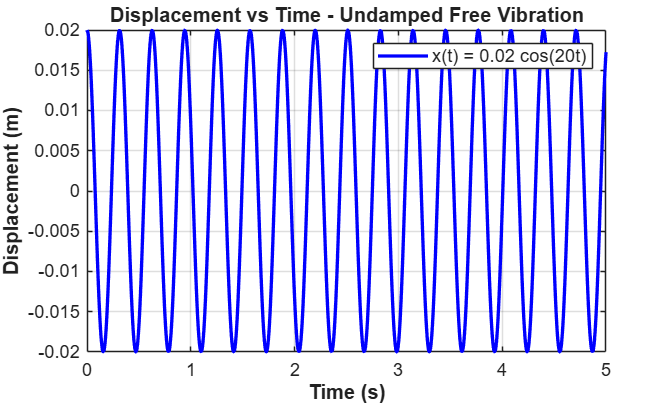


% 1.2 & 1.3: Time vector and displacement computation
t = linspace(0, 5, 1000);  % 0 to 5 seconds
x = x0 * cos(omega_n * t);

% Plot displacement
figure(1)
plot(t, x, 'b-', 'LineWidth', 2)
grid on
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('Displacement (m)', 'FontSize', 12, 'FontWeight', 'bold')
title('Displacement vs Time - Undamped Free Vibration', 'FontSize', 14, 'FontWeight', 'bold')
legend(sprintf('x(t) = %.2f cos(%.0ft)', x0, omega_n), 'FontSize', 11)
xlim([0 5])
set(gca, 'FontSize', 11)


% 1.4: Velocity computation and plot
v = -x0 * omega_n * sin(omega_n * t);
v_max = x0 * omega_n;
fprintf('1.4 Maximum velocity: %.2f m/s\n\n', v_max);

1.4 Maximum velocity: 0.40 m/s



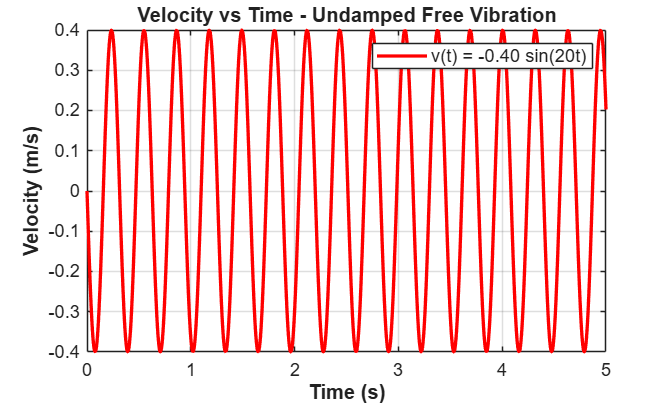


figure(2)
plot(t, v, 'r-', 'LineWidth', 2)
grid on
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('Velocity (m/s)', 'FontSize', 12, 'FontWeight', 'bold')
title('Velocity vs Time - Undamped Free Vibration', 'FontSize', 14, 'FontWeight', 'bold')
legend(sprintf('v(t) = -%.2f sin(%.0ft)', v_max, omega_n), 'FontSize', 11)
xlim([0 5])
set(gca, 'FontSize', 11)

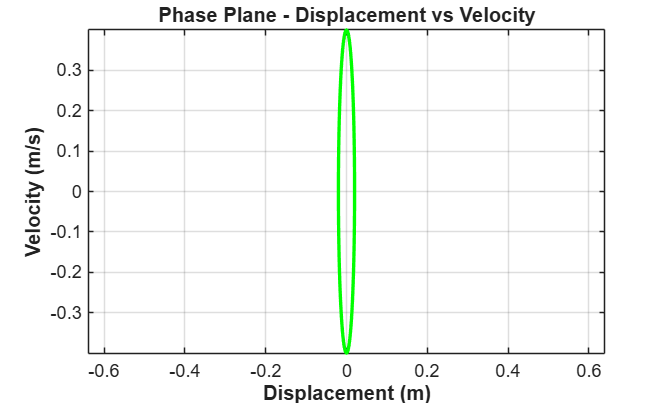


% Optional: Phase plane plot
figure(3)
plot(x, v, 'g-', 'LineWidth', 2)
grid on
xlabel('Displacement (m)', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('Velocity (m/s)', 'FontSize', 12, 'FontWeight', 'bold')
title('Phase Plane - Displacement vs Velocity', 'FontSize', 14, 'FontWeight', 'bold')
axis equal
set(gca, 'FontSize', 11)